% 1. Go to simulated data folder

SimulationName='Simulation_AfterRivisingFunctions_20231208';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/';
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/Simulation_manuscript/Simulation_AfterRivisingFunctions_20231208/'

cd(filepath)

% 5. define the double exponential decay parameters and other parameters in
% the simulation

p1_samples=0.4:0.01:0.6; % simulate the p1 range
tau1=2.14; % tau1 
tau2=0.69; % tau2

afterpulse_ratio=0.0032; 

SS_samples=100000:50000:1000000; % simulated sample size range.

load("AKAR_baseline_fitting_parameters.mat")
load('Autofluo_fitting_parameters')

PrfName = 'Prf_interp1.mat' % New file name of the prf file

PrfName = 'Prf_interp1.mat'


bkgrd_AP_distribution = zeros(1, 256) + 1/251; 
bkgrd_AP_distribution([1,2,3,4,256]) = 0; % Probability density distribution for background: background evenly distributed over time, but channel 1-4 and 256 as 0;
bkgrd_AP_sum = round(autofluo_bkgrd*251); % background total number

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## **This session is for perform fitting and lifetime calculation on the simulated samples. It has three steps of fitting and calculation followed by calculating the average fitted p1 and average lifetime and plot the heatmap.**

% 1. After generating the simulated samples, do 3 steps of fitting: sensor
% only; sensor + autofluorescence; sensor + autofluorescence + afterpulse +
% background

% Before doing each fitting, run spc_drawInit to call out the FLIM gui;
% load the delta peak time corrected PRF.
% Set the fitting range from 0.489 to 11.5

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% fitting step 1: with only sensor fluorescence samples
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ch = 1; % only for FLIM channel 1
load('Prf_interp1.mat')
spc.fits{1}.prf = prf;
spc.datainfo.psPerUnit = (12.5/256)*1000;
SS_samples=100000:50000:800000; % Figure 1 only plot photon count from 100000 to 8000000


for i = 1:length(p1_samples) % Running fitting from each p1 conditions

    % Load simulated sensor data from saved file with different p1 condition
    p1=p1_samples(i);
    simulated_name = ['/Volumes/PcSSDA/Simulated_data/', num2str(p1), '_sensor.mat'];
    load(simulated_name)

    % Initialize the variables to save the fitting parameters
    p1_fitted = zeros(500, length(SS_samples));  % fitted p1
    tau_avg = zeros(500, length(SS_samples)); % lifetime calculated based on the fitting curve calculated to infinite
    tau_avgTrunc = zeros(500, length(SS_samples)); % lifetime calculated based on the fitting curve within fitting range
    tau_empTrunc = zeros(500, length(SS_samples)); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
    chi2 = zeros(500, length(SS_samples)); % chi square from fitting
    beta6 = zeros(500, length(SS_samples)); % SHG term from fitting
    backcorr = zeros(500, length(SS_samples)); % background term from fitting

    for j = 1:length(SS_samples) % Under each sample size condition

        for k = 1:500 % 500 repeats of simulation

            % load simulated sample n

            spc.lifetimes{1} = n_sensor_simulated{j}(k,:); % assign the value to spc.lifetimes for fitting

            % initiate the fitting parameters
            
            spc.fits{1}.beta1 = 10000; % p1 and p2 as 0.5
            spc.fits{1}.beta3 = 10000;
            spc.fits{1}.beta5 = 0; % Delta peak time and SHG are fixed as 0
            spc.fits{1}.beta6 = 0;

            % Running the fitting
            spc_fitexp2prfGY(ch); 

            % collect parameters after fitting
            p1_fitted(k,j)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
            tau_avg(k,j)=spc.fits{ch}.avgTau; 
            tau_avgTrunc(k,j)=spc.fits{ch}.avgTauTrunc;
            tau_empTrunc(k,j)=spc.fits{ch}.EmpTauTrunc;
            chi2(k,j)=spc.fits{ch}.redchisq;
            beta6(k,j)=spc.fits{ch}.beta6;
            backcorr(k,j)=spc.fits{ch}.backCorr;

            
        end
    end

    % save the fitting parameters for each p1 conditon
    savename = ['Results_20231218_1_', num2str(i), '.mat'];
    save(savename, 'p1_fitted','tau_avg','tau_avgTrunc','tau_empTrunc','chi2','beta6','backcorr')


    
end

Error using load
Unable to find file or directory
'/Volumes/PcSSDA/Simulated_data/0.4_sensor.mat'.


% Results_20231201_1_: sensor only, fix delta peak time and SHG at 0

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% fitting step 2: sensor fluorescence and autofluorescence
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ch = 1; % only for FLIM channel 1
load('Prf_interp1.mat')
spc.fits{1}.prf = prf;
spc.datainfo.psPerUnit = (12.5/256)*1000;
SS_samples=100000:50000:800000; % Figure 1 only plot photon count from 100000 to 8000000


for i = 1:length(p1_samples) % Running fitting from each p1 conditions

    % Load simulated sensor data from saved file with different p1 condition
    p1=p1_samples(i);
    simulated_name = ['/Volumes/PcSSDA/Simulated_data/', num2str(p1), '_sensor.mat'];
    load(simulated_name)

    % Initialize the variables to save the fitting parameters
    p1_fitted = zeros(500, length(SS_samples));  % fitted p1
    tau_avg = zeros(500, length(SS_samples)); % lifetime calculated based on the fitting curve calculated to infinite
    tau_avgTrunc = zeros(500, length(SS_samples)); % lifetime calculated based on the fitting curve within fitting range
    tau_empTrunc = zeros(500, length(SS_samples)); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
    chi2 = zeros(500, length(SS_samples)); % chi square from fitting
    beta6 = zeros(500, length(SS_samples)); % SHG term from fitting
    backcorr = zeros(500, length(SS_samples)); % background term from fitting

    for j = 1:length(SS_samples) % each sample size condition

        % Load simulated autofluorescence data from saved file with different sample size condition
        SS = SS_samples(j);
        autoF_simulated_name = ['/Volumes/PcSSDA/Simulated_data/autoF_',num2str(SS), '.mat'];
        load(autoF_simulated_name)

        for k = 1:500 % 500 repeats of simulation

            % load simulated sample n

            spc.lifetimes{1} = n_sensor_simulated{j}(k,:) + n_auto_all(k, :); % Add up sensor fluorescence and autofluorescence and assign the value to spc.lifetimes for fitting

            % initiate the fitting parameters
            spc.fits{1}.beta1 = 10000; % p1 and p2 as 0.5
            spc.fits{1}.beta3 = 10000;
            spc.fits{1}.beta5 = 0; % Delta peak time and SHG are fixed as 0
            spc.fits{1}.beta6 = 0;

            % Running the fitting
            spc_fitexp2prfGY(ch);

            % collect parameters after fitting
            p1_fitted(k,j)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
            tau_avg(k,j)=spc.fits{ch}.avgTau; 
            tau_avgTrunc(k,j)=spc.fits{ch}.avgTauTrunc;
            tau_empTrunc(k,j)=spc.fits{ch}.EmpTauTrunc;
            chi2(k,j)=spc.fits{ch}.redchisq;
            beta6(k,j)=spc.fits{ch}.beta6;
            backcorr(k,j)=spc.fits{ch}.backCorr;

            
        end
    end

    % save the fitting parameters for each p1 conditon
    savename = ['Results_20231218_2_', num2str(i), '.mat'];
    save(savename, 'p1_fitted','tau_avg','tau_avgTrunc','tau_empTrunc','chi2','beta6','backcorr')


    
end

% Results_20231201_1_: sensor only, fix delta peak time and SHG at 0

% Results_20231201_2_: sensor and autofluorescence, fix delta peak time and SHG at 0

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% fitting step 3: sensor fluorescence + autofluorescence + afterpulse + background
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ch = 1; % only for FLIM channel 1
spc.datainfo.psPerUnit = (12.5/256)*1000;
SS_samples=100000:50000:800000; % Figure 1 only plot photon count from 100000 to 8000000

for i = 1:length(p1_samples) % each p1 condition

    % Load simulated sensor data from saved file with different p1 condition
    p1=p1_samples(i);
    simulated_name = ['/Volumes/PcSSDA/Simulated_data/', num2str(p1), '_sensor.mat'];
    load(simulated_name)

    % save the fitting parameters
    p1_fitted = zeros(500, length(SS_samples));  % fitted p1
    tau_avg = zeros(500, length(SS_samples)); % lifetime calculated based on the fitting curve calculated to infinite
    tau_avgTrunc = zeros(500, length(SS_samples)); % lifetime calculated based on the fitting curve within fitting range
    tau_empTrunc = zeros(500, length(SS_samples)); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
    chi2 = zeros(500, length(SS_samples)); % chi square from fitting
    beta6 = zeros(500, length(SS_samples)); % SHG term from fitting
    backcorr = zeros(500, length(SS_samples)); % background term from fitting

    for j = 1:length(SS_samples) % each sample size condition

        SS = SS_samples(j);
        % Load simulated autofluorescence data from saved file with different sample size condition
        autoF_simulated_name = ['/Volumes/PcSSDA/Simulated_data/autoF_',num2str(SS), '.mat'];
        load(autoF_simulated_name)
        % Load simulated background data from saved file with different sample size condition
        bkgrd_simulated_name = ['/Volumes/PcSSDA/Simulated_data/bkgrd_AP_',num2str(SS), '.mat'];
        load(bkgrd_simulated_name)

        for k = 1:500 % 500 repeats of simulation

            % load simulated sample n

            spc.lifetimes{1} = n_sensor_simulated{j}(k,:) + n_auto_all(k, :) + n_bkgrd_all(k, :); % Add up sensor fluorescence, autofluorescence, and background+afterpluse and assign the value to spc.lifetimes for fitting

            % initiate the fitting parameters
            
            spc.fits{1}.beta1 = 10000; % p1 and p2 as 0.5
            spc.fits{1}.beta3 = 10000;
            spc.fits{1}.beta5 = 0; % delta peak time and SHG as 0
            spc.fits{1}.beta6 = 0;

            spc_fitexp2prfGY(ch); % fitting
            spc_adjustTauOffset(ch); 


            % collect parameters after fitting
            p1_fitted(k,j)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
            tau_avg(k,j)=spc.fits{ch}.avgTau; 
            tau_avgTrunc(k,j)=spc.fits{ch}.avgTauTrunc;
            tau_empTrunc(k,j)=spc.fits{ch}.EmpTauTrunc;
            chi2(k,j)=spc.fits{ch}.redchisq;
            beta6(k,j)=spc.fits{ch}.beta6;
            backcorr(k,j)=spc.fits{ch}.backCorr;

            
        end
    end

    % save the fitting parameters for each p1 conditon
    savename = ['Results_20231218_3_', num2str(i), '.mat'];
    save(savename, 'p1_fitted','tau_avg','tau_avgTrunc','tau_empTrunc','chi2','beta6','backcorr')
    
end

% Results_20231201_1_: sensor only, fix delta peak time and SHG at 0

% Results_20231201_2_: sensor and autofluorescence, fix delta peak time and SHG at 0

% Results_20231201_3_: sensor, autofluorescence and background, fix delta peak time and SHG at 0

global FixBackground FixedBackground

FixBackground = 1;

ch = 1; % only for FLIM channel 1
load('Prf_interp1.mat')
spc.fits{1}.prf = prf;
spc.datainfo.psPerUnit = (12.5/256)*1000;
spc.fits{1}.fitstart = spc.datainfo.psPerUnit/1000;
spc.fits{1}.fitend = 12.5;

spc.fits{1}.beta2 = tau1; % p1 and p2 as 0.5

Unrecognized function or variable 'tau1'.

spc.fits{1}.beta4 = tau2;

sample_num = 500;
SS_samples=100000:50000:800000;

for i = 1:length(p1_samples) % Running fitting from each p1 conditions

    % Load simulated sensor data from saved file with different p1 condition
    p1=p1_samples(i);
    simulated_name = ['/Volumes/PcSSDA/Simulated_data/', num2str(p1), '_sensor.mat'];
    load(simulated_name)

    p1_fitted = zeros(sample_num, length(SS_samples));  % fitted p1
    tau_empTrunc = zeros(sample_num, length(SS_samples)); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
    fitting_parameters = {};


    for j = 1:length(SS_samples) % Under each sample size condition
        n_all = {};

        n_all{1} = n_sensor_simulated{j};

        % Load simulated autofluorescence data from saved file with different sample size condition
        SS = SS_samples(j);

        FixedBackground = (SS*afterpulse_ratio + bkgrd_AP_sum)/251;


        autoF_simulated_name = ['/Volumes/PcSSDA/Simulated_data/autoF_',num2str(SS), '.mat'];
        load(autoF_simulated_name)

        n_all{2} = n_auto_all;

        % Load simulated background data from saved file with different sample size condition
        bkgrd_simulated_name = ['/Volumes/PcSSDA/Simulated_data/bkgrd_AP_',num2str(SS), '.mat'];
        load(bkgrd_simulated_name)

        n_all{3} = n_bkgrd_all;

        [p1_fitted_single, tau_empTrunc_single, fitting_parameters_single] = RunFitting(sample_num, n_all);
        p1_fitted(:,j) = p1_fitted_single;
        tau_empTrunc(:,j) = tau_empTrunc_single;
        fitting_parameters{j} = fitting_parameters_single;

    end

    % save the fitting parameters for each p1 conditon
    savename = ['/Volumes/PcSSDA/Simulated_data/Results_20240328_NoBackground_', num2str(i), '.mat'];
    save(savename, 'p1_fitted','tau_empTrunc','fitting_parameters')

end


% Collect the fitted p1 data, calculated the mean and standard deviation of
% fitted p1 under each p1 and photon number condition

savename_postfix = 'Results_20231210_1_';
savename_postfix = 'Results_20231210_2_';
savename_postfix = 'Results_20231210_3_';

savename_postfix = 'Results_20231218_3_';

SS_samples=100000:50000:800000; % simulated sample size range.

% initialize the calculated p1, tau, and chi2 matrix
p1_mean_all = zeros(length(SS_samples), length(p1_samples));
p1_std_all = zeros(length(SS_samples), length(p1_samples));

for i = 1:length(p1_samples)
    p1=p1_samples(i);
    savename = [savename_postfix, num2str(i), '.mat']; 
    load(savename) % for each p1 condition, load the saved file, calculate the p1 and mean
    for j = 1:length(SS_samples)
        p1_mean_all(j,i) = mean(p1_fitted(:,j)); % mean p1
        p1_std_all(j,i) = std(p1_fitted(:,j)); % std p1

    end
end

% 5. for heatmap, construct the labels for x and y axis
SS_samples=100000:50000:800000;
x_labels_p1 = {};
for i = 1:length(p1_samples)
    if mod(i,3) == 1
        x_labels_p1{i} = num2str(p1_samples(i));
    else
        x_labels_p1{i} = ' ';
    end
end

y_labels_SS = {};
for i = 1:length(SS_samples)
    if mod(i,4) == 1
        y_labels_SS{i} = num2str(SS_samples(i)/10000);
    else
        y_labels_SS{i} = ' ';
    end
end

% Plot the heatmap of fitted p1 and empirical lifetime
figure
h = heatmap(p1_mean_all, 'ColorLimits', [0.375 0.61])
grid off
% colormap parula
colormap jet
h.Title = 'Fitted p1';
h.XLabel = 'P1';
h.YLabel = 'Phonton number (x10^4)';
h.XDisplayLabels = x_labels_p1;
h.YDisplayLabels = y_labels_SS;

% Three steps to calculate the empirical lifetime:
% 1. sensor only
% 2. sensor and autofluorescence
% 3. sensor, autofluorescence and background and afterpulse

fit_range = [10 235]; % Fitting range is from 0.0489 to 11.5 ns, which is transformed into channel 10 to 235
x_axis = (1:1:(fit_range(2) - fit_range(1) + 1))*(12.5/256); % Lifetime values corresponding to the fitting range

% P1 and sensor photon number conditions for the simulation
p1_samples = 0.4:0.01:0.6;
SS_samples = 100000:50000:800000;

% Initialize the mean and standard deviation variable
tau_mean_all = zeros(length(SS_samples), length(p1_samples));
tau_std_all = zeros(length(SS_samples), length(p1_samples));

% Initialize the variable to save the calculated empirical lifetime for each simulated data
tau_all = {};

for i = 1:length(p1_samples)
    % Load simulated sensor data for each p1 condition
    sensor_file_name = ['Simulated_data/', num2str(p1_samples(i)), '_sensor.mat'];
    load(sensor_file_name)

    for j = 1:length(SS_samples)

        % Load simulated autofluorescence data from saved file with different sample size condition
        autoF_file_name = ['Simulated_data/autoF_', num2str(SS_samples(j)), '.mat'];
        load(autoF_file_name)

        % Load simulated background data from saved file with different sample size condition
        bkgrd_file_name = ['Simulated_data/bkgrd_AP_', num2str(SS_samples(j)), '.mat'];
        load(bkgrd_file_name)

        tau_sim = zeros(1, 500);

        for k = 1:500

%             n_final = n_sensor_simulated{j}(k,:);
%             n_final = n_sensor_simulated{j}(k,:) + n_auto_all(k, :);
            n_final = n_sensor_simulated{j}(k,:) + n_auto_all(k, :) + n_bkgrd_all(k, :);

            tau_sim(k) = sum(n_final(fit_range(1):fit_range(2)).*x_axis)/sum(n_final(fit_range(1):fit_range(2)));

        end

        tau_mean_all(j,i) = mean(tau_sim);
        tau_std_all(j,i) = std(tau_sim);
        tau_all{j,i} = tau_sim;
    end
end

% save('Tau_SensorOnly.mat', 'tau_mean_all', 'tau_std_all', 'tau_all')
% save('Tau_Sensor_autoF.mat', 'tau_mean_all', 'tau_std_all', 'tau_all')
save('Tau_final.mat', 'tau_mean_all', 'tau_std_all', 'tau_all')

% 6. plot the heatmap of fitted p1 and empirical lifetime
% load('Tau_SensorOnly.mat')
% load('Tau_Sensor_autoF.mat')
load('Tau_final.mat')

figure
h = heatmap(tau_mean_all, 'ColorLimits', [3.35 3.6])

h =   HeatmapChart with properties:

        XData: {21×1 cell}
        YData: {15×1 cell}
    ColorData: [15×21 double]

  Show all properties


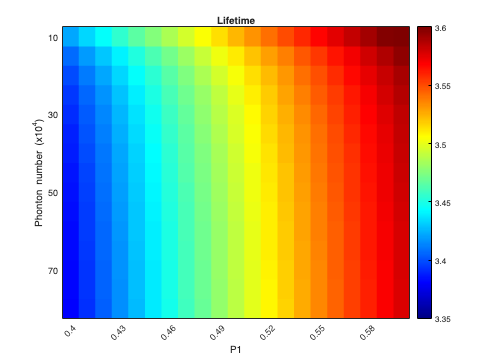

grid off
colormap jet
% colormap parula
h.Title = 'Lifetime';
h.XLabel = 'P1';
h.YLabel = 'Phonton number (x10^4)';
h.XDisplayLabels = x_labels_p1;
h.YDisplayLabels = y_labels_SS;

% The next twp sections are for running the statistical t test on the fitted
% p1 and empirical lifetime between three conditions (sensor only, sensor/autoF, final data)
savename_postfix = {};

p1_fitted_test05 = {};
tau_test05 = {};

savename_postfix{1} = 'Results_20231218_1_';
savename_postfix{2} = 'Results_20231218_2_';
savename_postfix{3} = 'Results_20231218_3_';

i = 11;
for j = 1:3
    savename = [savename_postfix{j}, num2str(i), '.mat'];
    load(savename)
    p1_fitted_test05{j} = p1_fitted;
    tau_test05{j} = tau_empTrunc;
end


t_test_p1 = {};
t_test_tau = {};
for j = 1:3
    t_test_p1{j} = zeros(1,15);
    t_test_tau{j} = zeros(1,15);
end

comparisons = {[1 2], [1 3], [2 3]};

for j = 1:3
    for i = 1:15
        t_test_p1{j}(i) = 15*ranksum(p1_fitted_test05{comparisons{j}(1)}(:,i), p1_fitted_test05{comparisons{j}(2)}(:,i));
        t_test_tau{j}(i) = 15*ranksum(tau_test05{comparisons{j}(1)}(:,i), tau_test05{comparisons{j}(2)}(:,i));
    end
end

function [p1_fitted, tau_empTrunc, fitting_parameters] = RunFitting(sample_num, n_all)

global spc
ch = 1;

pop1 = zeros(sample_num, 1);  % population 1
pop2 = zeros(sample_num, 1);  % population 2
p1_fitted = zeros(sample_num, 1);  % fitted p1
tau_avg = zeros(sample_num, 1); % lifetime calculated based on the fitting curve calculated to infinite
tau_avgTrunc = zeros(sample_num, 1); % lifetime calculated based on the fitting curve within fitting range
tau_empTrunc = zeros(sample_num, 1); % lifetime calculated empirically based on fitting range. This will be the average lifetime I use
chi2 = zeros(sample_num, 1); % chi square from fitting
beta6 = zeros(sample_num, 1); % SHG term from fitting
backcorr = zeros(sample_num, 1); % background term from fitting

fitting_parameters = {};

for k = 1:sample_num

    spc.lifetimes{1} = n_all{1}(k,:);

    if length(n_all) > 1

        for i_components = 2:length(n_all)

            spc.lifetimes{1} = spc.lifetimes{1} + n_all{i_components}(k,:);
        end

    end


    % initiate the fitting parameters
            
    spc.fits{1}.beta1 = 10000; % p1 and p2 as 0.5
    spc.fits{1}.beta3 = 10000;
    spc.fits{1}.beta5 = 0; % Delta peak time and SHG are fixed as 0
    spc.fits{1}.beta6 = 0;

    % Running the fitting
    spc_fitexp2prfGY(ch); 

    pop1(k,1) = spc.fits{ch}.beta1;
    pop2(k,1) = spc.fits{ch}.beta3;
    p1_fitted(k,1)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3); 
    tau_avg(k,1)=spc.fits{ch}.avgTau; 
    tau_avgTrunc(k,1)=spc.fits{ch}.avgTauTrunc;
    tau_empTrunc(k,1)=spc.fits{ch}.EmpTauTrunc;
    chi2(k,1)=spc.fits{ch}.redchisq;
    beta6(k,1)=spc.fits{ch}.beta6;
    backcorr(k,1)=spc.fits{ch}.backCorr;

end

fitting_parameters{1} = tau_avg;
fitting_parameters{2} = tau_avgTrunc;
fitting_parameters{3} = chi2;
fitting_parameters{4} = beta6;
fitting_parameters{5} = backcorr;
fitting_parameters{6} = pop1;
fitting_parameters{7} = pop2;

end